# 1.0 Human vs Machine Learning

Let's take a closer look at the difference between how we learn as humans and how machines learn.

Consider this relation between two variables, $x$ and $y$. 

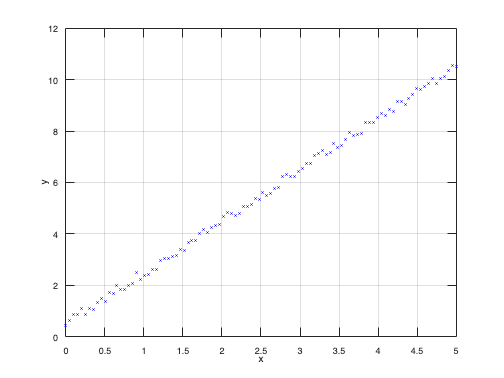

clear; 
m = 2; b = 0.5;
x = linspace(0,5,100);
y = randomfluctuations(x,m,b,0.4);
plot(x,y,'bx','MarkerSize',5)
xlabel('x'); ylabel('y');
grid on

*Figure 1.1. A data set that forms a straight line. But the computer doesn't know it's a straight line.*

## 1.1 How we determine the best fit line

We know instinctively that this data forms a straight line, even though there's a little bit of randomness in the line. We know that we can plot a straight line that will represent this data. The straight line that fits this data set is given by $y=mx+b$, where $m$ is the slope and $b$ is the y-intercept. We can get the slope and the y-intercept using three methods. The first is we get a ruler and we draw a line that roughly passes through these points. We see that it intersects the y-axis at some point and we call that point our y-intercept. Then, we count the number of grid lines that represents the rise along the y-axis and the run along the x-axis to estimate the slope. The second method is we estimate the error between these data points and the expected value, represented by the equation of a line, and we minimize that error by doing some calculus. Minimizing gives us the slope and the y-intercept. We know this because these are the rules that mathematics taught us. 

Of course, the third method is to use the tools available to us in MATLAB.

model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    0.45103      0.023178    19.459    1.9609e-35
    x1              2.0152     0.0080091    251.62    1.479e-139


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.117
R-squared: 0.998,  Adjusted R-Squared: 0.998
F-statistic vs. constant model: 6.33e+04, p-value = 1.48e-139

model.Coefficients

ans = 2×4 table
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)    0.45103      0.023178    19.459    1.9609e-35
    x1              2.0152     0.0080091    251.62    1.479e-139


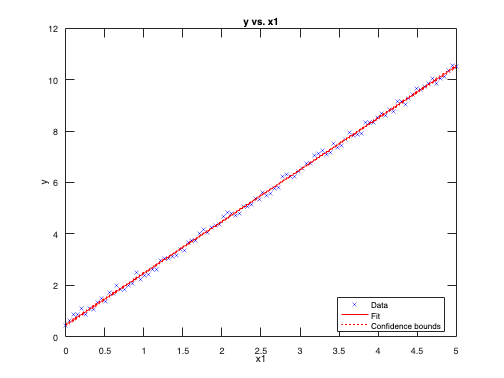

plot(model)

*Figure 1.2. Predicted best fit line using the linear regression algorithm of MATLAB.*

## 1.2 How a computer determines the best fit line

A computer doesn't know any of these rules. What the computer does after it gets the data is that it'll make several guesses for the slope and the y-intercept until the error becomes really small. In each guess, it rewrites some parameters that it uses so that the error becomes smaller and smaller. When the error is small enough, then the computer returns the final value of the slope and the y-intercept to represent the line. After all of that, the computer still doesn't know what the mathematical rules are.

This short code is a machien learning model that will solve for the best fit line of the given data $x$ and $y$.

% Alternative 1
layers = [
    sequenceInputLayer(1,"MinLength",length(x))
    fullyConnectedLayer(1)
    regressionLayer
    ];
options = trainingOptions("sgdm","MaxEpochs",100,"InitialLearnRate",0.0001,...
    "Plots","training-progress")

options =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-04
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                       MaxEpochs: 100
                   MiniBatchSize: 128
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
                      WorkerLoad: []
                       OutputFcn: []
  

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |         3.17 |          5.0 |      1.0000e-04 |
|      50 |          50 |       00:00:02 |         0.22 |      2.4e-02 |      1.0000e-04 |
|     100 |         100 |       00:00:03 |         0.12 |      6.7e-03 |      1.0000e-04 |
|========================================================================================|
Training finished: Max epochs completed.


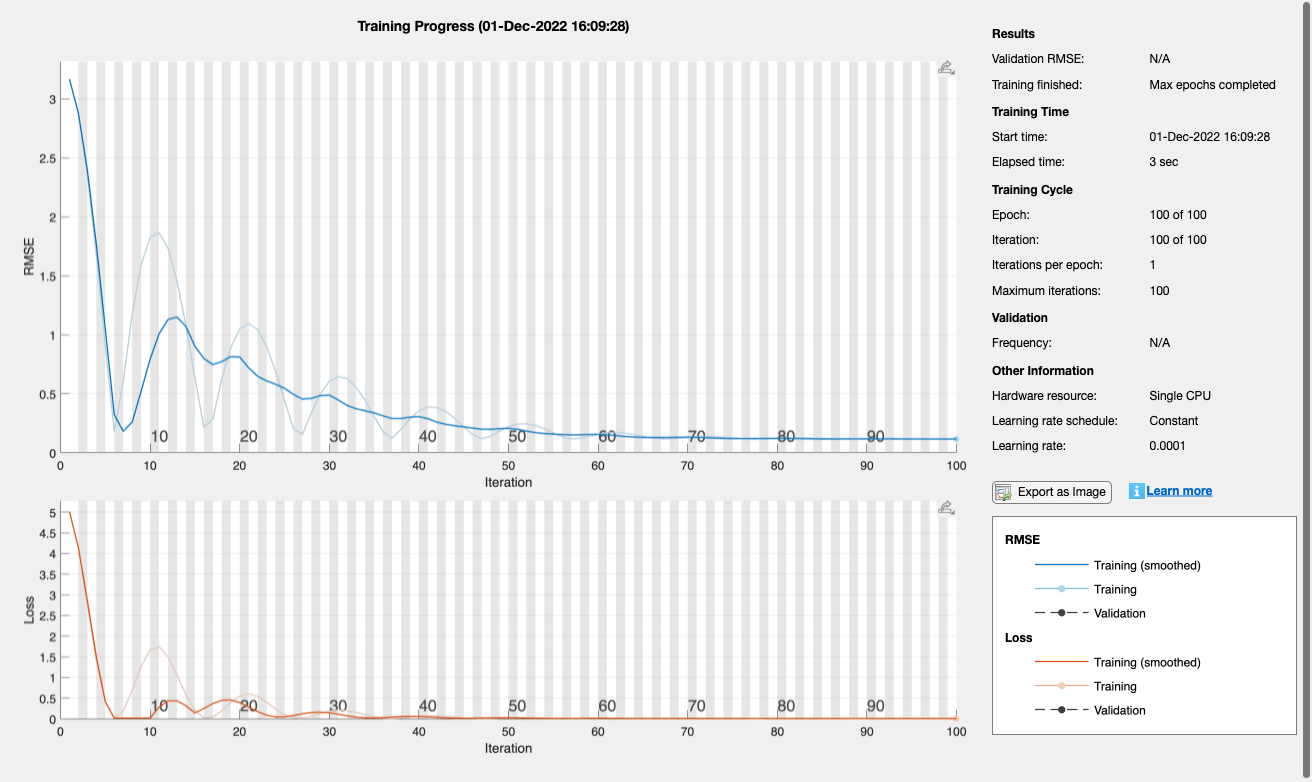

net = trainNetwork(x,y,layers,options);

As you can see from the code, it does not directly give out a numerical value for the slope and the y-intercept. It does, however, give out the best fit line to a certain margin of error of $y$ for a given value of $x$ based on the data. 

xtest = 3

xtest = 3

ytest = net.predict(xtest)

ytest = single
6.4832

yactual = m*xtest + b;
error = 100*abs(yactual-ytest)/yactual

error = single
0.2588

% % Alternative 2
% net = fitnet(1,'trainscg');  %% algorithm is a scaled conjugate gradient
%                              %% with gradient descent ('traingd') and gradient descent with momentum ('traingdm')
%                              %% the fittings are non-linear
% % view(net);
% [net,tr] = train(net,x,y);
% % view(net);
% ypred = net(x);             %% solves for the predicted value given the x data
% perf = perform(net,x,y);    %% solves for the mean-squared error

## 1.3 Comparing human vs machine learning

Comparing with the actual value of 6.5, we have an error that is about 0.15%. If we plot the predicted data set against the given data set, we have this result.

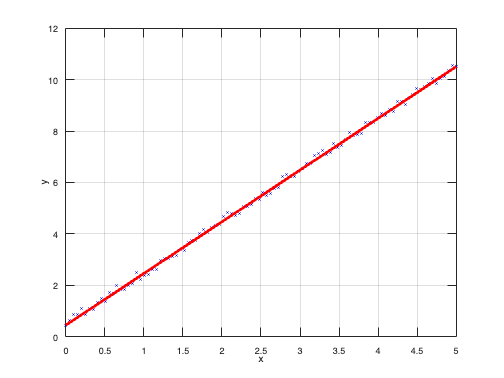

ypred = predict(net,x);
plot(x,y,'bx','MarkerSize',5)
hold on
plot(x,ypred,'r','LineWidth',3)
xlabel('x'); ylabel('y');
grid on
hold off

*Figure 1.3. Predicted best fit line by the machine learning model.*

Why are we still solving for the error even if the calculations were performed by a computer? As you will soon learn, computers learn based on statistical techniques, which is why their guesses will not always be exact. To a computer, the result indicated by the red line in the graph is the most probable result from the given data.